% A=[1;1;1;1;1;1]
% A=zeros(6,1)
% A=zeros(3,6)
A=zeros(3,6);
sym(A)

$$ans = \left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

sym([1,1,1,1,1,1])

$$ans = \left(\begin{array}{cccccc} 1 & 1 & 1 & 1 & 1 & 1 \end{array}\right)$$

format short

% Task1
M = 10; %масса тележки
m1 = 1; %масса маятника 1
m2 = 2; %масса маятника 2
l1 = 2; %длина маятника 1
l2 = 1; %длина маятника 2
g = 10; %ускорение свпад

% A = [0 1 0 0 0 0;
%     0 0 m1*g/(M+m1+m2) m2*g/(M+m1+m2) 0 0;
%     0 0 0 0 1 0;
%     0 0 0 0 0 1;
%     0 0 -(M+m1+m2)*g/m1/l1 0 0 0;
%     0 0 0 (M+m1+m2)*g/m2/l2 0 0];
% sym(A);
% B = [0; 1/(M+m1+m2); 0; 0; -(M+m1+m2)/m1^2/l1; -(M+m1+m2)/m2^2/l2];
% C = [1 0 0 0 0 0; 0 0 1 0 0 0; 0 0 0 1 0 0];
% D = [0 0; 1/(M+m1+m2)/l1 1/(M+m1+m2)/l2; 0 0; 0 0; (M+m1+m2)/m1^2/l1^2 0; 
%     0 (M+m1+m2)/m2^2/l2^2];

A = [0 1 0 0 0 0;
    0 0 m1*g/M -m2*g/M 0 0;
    0 0 0 0 1 0;
    0 0 0 0 0 1;
    0 0 (M+m1)*g/M/l1 -m2*g/M/l1 0 0;
    0 0 -m1*g/M/l2 (M+m2)*g/M/l2 0 0];
B = [0; 1/M; 0; 0; 1/M/l1; -1/M/l2];
C = [1 0 0 0 0 0; 0 0 1 0 0 0; 0 0 0 1 0 0];
D = [0 0; 1/M/l1 -1/M/l2; 0 0; 0 0; (M+m1)/M/m1/l1^2 -1/M/l1/l2; 
    -1/M/l1/l2 (M+m2)/M/m2/l2^2]

D =          0         0
    0.0500   -0.1000
         0         0
         0         0
    0.2750   -0.0500
   -0.0500    0.6000


sym(D);
Dblock = zeros(3,1);
sys = ss(A,B,C,0); 

%Task2.1 
eig(A)

ans =          0
         0
    3.4857
    2.3129
   -2.3129
   -3.4857


[P_complex, A_jordan_complex] = eig(A)

P_complex =     1.0000   -1.0000   -0.0475   -0.0509    0.0509    0.0475
         0    0.0000   -0.1657   -0.1177   -0.1177   -0.1657
         0         0   -0.0404   -0.3892    0.3892    0.0404
         0         0    0.2686   -0.0585    0.0585   -0.2686
         0         0   -0.1408   -0.9002   -0.9002   -0.1408
         0         0    0.9363   -0.1354   -0.1354    0.9363


A_jordan_complex =          0         0         0         0         0         0
         0         0         0         0         0         0
         0         0    3.4857         0         0         0
         0         0         0    2.3129         0         0
         0         0         0         0   -2.3129         0
         0         0         0         0         0   -3.4857


sym(round(P_complex,3));

U = ctrb(sys); %матрица управляема
rank(U)

ans = 6

% e1_hautus = [(A - A_jordan_complex(6,6)*eye(6)) B];
% rank_e1_hautus = rank(e1_hautus) %проверка собств чисел

V = obsv(sys); %матрица набюдаема
rank(V)

ans = 6


%Task2.2
syms s
W=C*(s*eye(6)-A)^(-1)*[B D];
simplify(W)

$$ans = \begin{array}{l} \left(\begin{array}{ccc} \frac{s^{4}-15\,s^{2}+50}{5\,s^{2}\,\sigma_{3}} & \sigma_{2} & \sigma_{1}\\ \sigma_{2} & \frac{11\,s^{2}-130}{20\,\sigma_{3}} & -\frac{s^{2}}{10\,\sigma_{3}}\\ \sigma_{1} & -\frac{s^{2}}{10\,\sigma_{3}} & \frac{12\,s^{2}-65}{10\,\sigma_{3}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{s^{2}-5}{5\,\sigma_{3}}\\ \sigma_{2}=\frac{s^{2}-10}{10\,\sigma_{3}}\\ \sigma_{3}=2\,s^{4}-35\,s^{2}+130 \end{array}$$

[N,D] = numden(W);
coefnum = coeffs(D(1,2), "All")

$$coefnum = \left(\begin{array}{ccccc} 20 & 0 & -350 & 0 & 1300 \end{array}\right)$$

pole(tf(1,[20 0 -350 0 1300]))

ans =    -3.4857
   -2.3129
    3.4857
    2.3129


coefnum = coeffs(N(3,3), "All")

$$coefnum = \left(\begin{array}{ccc} 12 & 0 & -65 \end{array}\right)$$

zero(tf([12 0 -65],1))

ans =     2.3274
   -2.3274



$$x$$
 
$$v$$
 
$$\varphi_1$$

$$\varphi_2$$
 
$$\omega_1$$

$$\omega_2$$


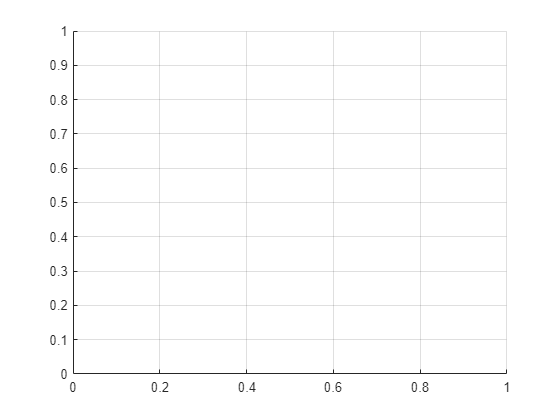

%Task2.3
x1 = [0 0 0 0 0 0];
D1 = D(:,1);
D2 = D(:,2);
% D1 = [0; 1/(M+m1+m2)/l1; 0; 0; (M+m1+m2)/m1^2/l1^2; 0];
% D2 = [0; 1/(M+m1+m2)/l2; 0; 0; 0; (M+m1+m2)/m2^2/l2^2];
figure; %векторы
grid on;
hold on;

plot(out.x.Time, out.x.Data(:, 1), 'b', 'LineWidth', 2)

Unable to resolve the name 'out.x.Time'.

plot(out.x.Time, out.x.Data(:, 2), 'r', 'LineWidth', 2)
plot(out.x.Time, out.x.Data(:, 3), 'LineWidth', 2)
plot(out.x.Time, out.x.Data(:, 4), 'LineWidth', 2)
plot(out.x.Time, out.x.Data(:, 5), 'LineWidth', 2)
plot(out.x.Time, out.x.Data(:, 6), 'LineWidth', 2)
xlabel("Time (seconds)"), ylabel("Amplitude")
legend("x","v_2","\phi_3","\phi_4","\omega_5","\omega_6")
xlim([0 2])
ylim([-20 20])